## Ali Saeizadeh - 810196477

## Section 1

### 1.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
modulation = 'pam';             % Modulation Name ('psk', 'pam', 'qam', 'fsk')
k = 2;                          % Bit Per Symbol
M = 2^k;  
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


### 2.

flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0     0
     0     1
     1     1
     1     0



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      1
     3
     1
     1
     2
     2
     2
     1
     1
     4


[cons, Es_avg] = constellation(M, modulation)

cons =    -1.3416
   -0.4472
    0.4472
    1.3416


Es_avg = 1

mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
mod_sym

mod_sym =    -1.3416
    0.4472
   -1.3416
   -1.3416
   -0.4472
   -0.4472
   -0.4472
   -1.3416
   -1.3416
    1.3416


### 3

pulse_shape_mode = 'kron'

pulse_shape_mode = 'kron'

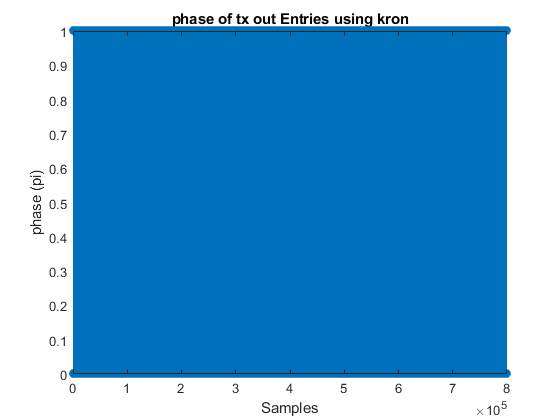

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(angle(tx_smpl)/pi, 'filled')
title('phase of tx out Entries using kron')
xlabel('Samples')
ylabel('phase (pi)')

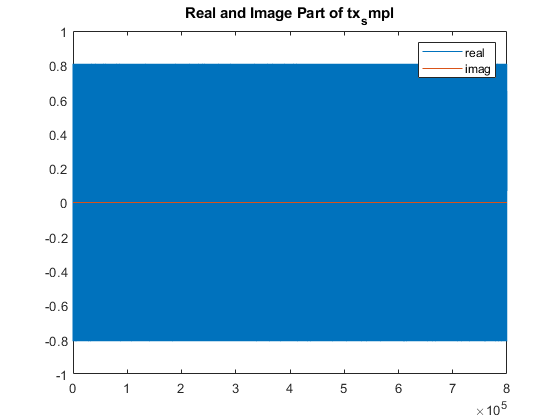


plot([real(tx_smpl), imag(tx_smpl)])
title('Real and Image Part of tx_smpl')
legend('real','imag')

pulse_shape_mode = 'conv'

pulse_shape_mode = 'conv'

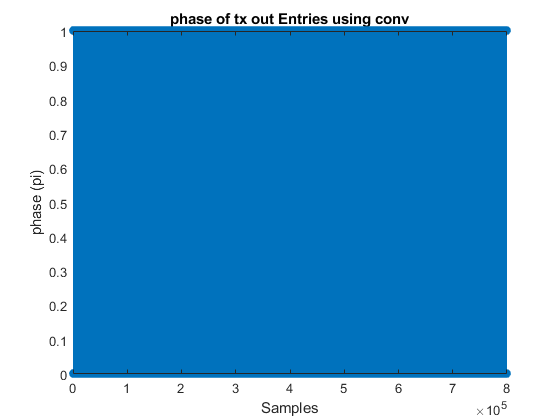

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(angle(tx_smpl)/pi, 'filled')
title('phase of tx out Entries using conv')
xlabel('Samples')
ylabel('phase (pi)')


plot([real(tx_smpl), imag(tx_smpl)])
title('Real and Image Part of tx_smpl')
legend('real','imag')

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  Es_avg/log2(M) 

Eb = 0.5000

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.0500

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =    0.0869 + 0.1453i
   0.2025 + 0.0202i
   0.0870 + 0.0376i
   0.0918 + 0.0589i
   0.1214 + 0.0446i
   0.0129 - 0.0365i
  -0.0629 + 0.2009i
   0.0052 + 0.0545i
  -0.1422 + 0.0013i
  -0.0103 - 0.0334i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.0869 + 0.1453i
   0.0003 + 0.0202i
  -0.3175 + 0.0376i
  -0.5150 + 0.0589i
  -0.6876 + 0.0446i
  -0.5938 - 0.0365i
  -0.4675 + 0.2009i
  -0.1970 + 0.0545i
  -0.1422 + 0.0013i
   0.0571 - 0.0334i


rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'pam'

M = 4

fs = 10000000

smpl_per_symbl = 8

pulse_name = 'triangular'

rx_mode = 'matched_filter'

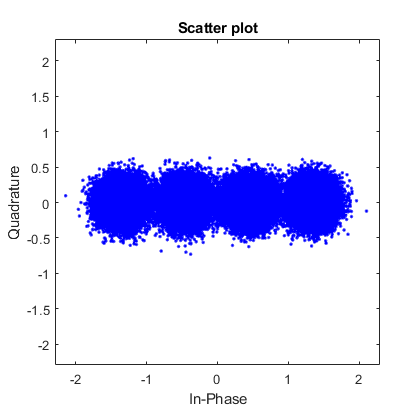

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)

det_bit = b_code(det_sym_idx,:)

det_bit =      0     0
     1     1
     0     0
     0     0
     0     1
     0     1
     0     1
     0     0
     0     0
     1     0


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 0.0036

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 0.0018

serPSK = zeros(size(snr_db));
berPSK = zeros(size(snr_db));
for i = 0:1:3
    Eb =  Es_avg/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serPSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berPSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


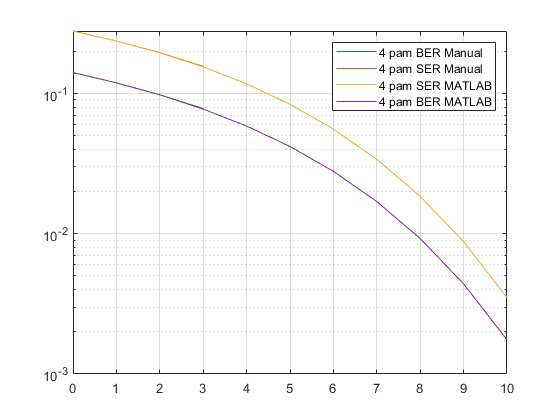


figure
[berPSK_matlab, serPSK_matlab] = berawgn(snr_db,modulation,M);
semilogy(snr_db,berPSK)
hold on
semilogy(snr_db,serPSK)
hold on
semilogy(snr_db,serPSK_matlab)
hold on
semilogy(snr_db,berPSK_matlab)
legend(sprintf('%d %s BER Manual',M,modulation),sprintf('%d %s SER Manual',M,modulation), sprintf('%d %s SER MATLAB',M,modulation), sprintf('%d %s BER MATLAB',M,modulation))
grid on

figure